
num=1;
den=[1 10 20];
g=tf(num,den)


g =
 
         1
  ---------------
  s^2 + 10 s + 20
 
Continuous-time transfer function.



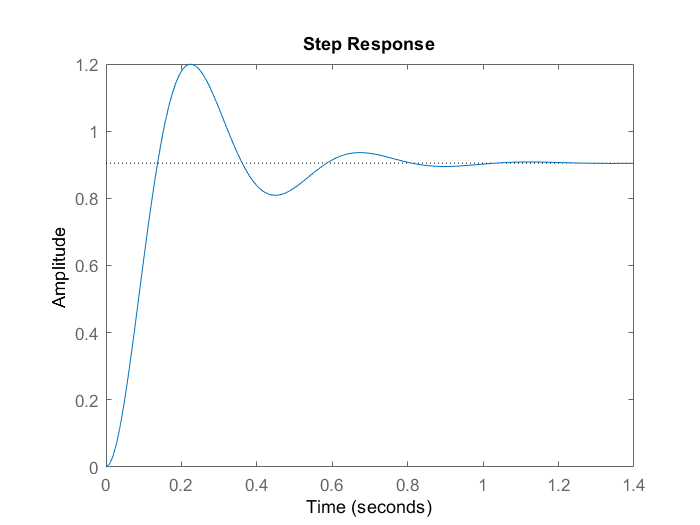

t=feedback(g,1);

kp=200;
ki=0;
kd=0;
cont=pid(kp);
step(feedback(cont*t,1));

stepinfo(feedback(cont*t,1))

ans = struct with fields:
        RiseTime: 0.0925
    SettlingTime: 0.7456
     SettlingMin: 0.8091
     SettlingMax: 1.1993
       Overshoot: 32.5220
      Undershoot: 0
            Peak: 1.1993
        PeakTime: 0.2210


k=dcgain(cont*t);
1/(1+k)

ans = 0.0950